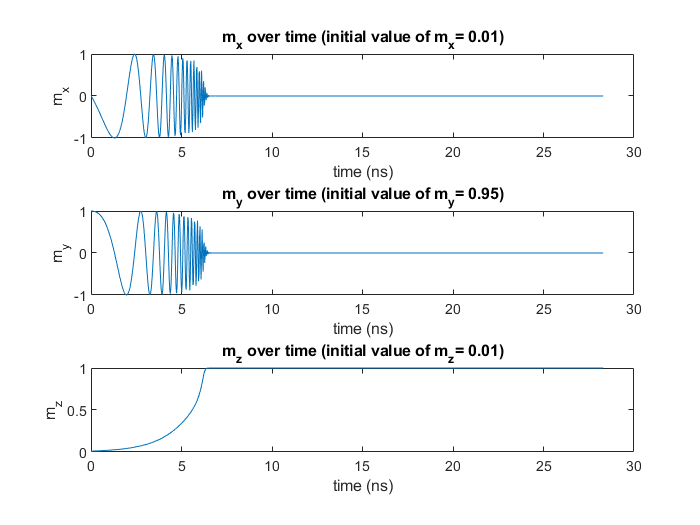

clc;
clear all;
close all;

global alpha;
alpha = 0.01;
gamma = 2.21276e5;
mu = 1.2566e-6;
h_k = 3.1951e5;
m_initial=[0.01, 0.95, 0.01];
m_norm = m_initial/norm(m_initial);

tau1 = 0;
tau2 = 2000;
N = 1000;
h = (tau2 - tau1) / N;
tau = linspace(tau1, tau2, N+1);

m = zeros(N+1, 3);
m(1, :)=m_norm;

for i = 1:N
    k1 = h*llg(m(i, :), alpha);
    k2 = h*llg(m(i, :) + 0.5*k1, alpha);
    k3 = h*llg(m(i, :) + 0.5*k2, alpha);
    k4 = h*llg(m(i, :) + k3, alpha);

    m(i+1, :) = m(i, :) + (1/6) * (k1 + 2*k2 + 2*k3 + k4);
    m(i+1, :) = m(i+1, :) / norm(m(i+1, :));
end

time = tau * (1 + alpha^2) / (gamma * h_k);

figure;
subplot(3,1,1);
plot(time * 1e9, m(:,1));
xlabel('time (ns)');
ylabel('m_x');
title(['m_x over time (initial value of m_x= ',num2str(m_initial(1)),')'])

subplot(3,1,2);
plot(time * 1e9, m(:,2));
xlabel('time (ns)');
ylabel('m_y');
title(['m_y over time (initial value of m_y= ',num2str(m_initial(2)),')'])

subplot(3,1,3);
plot(time * 1e9, m(:,3));
xlabel('time (ns)');
ylabel('m_z');
title(['m_z over time (initial value of m_z= ',num2str(m_initial(3)),')'])

function llg = llg(m, alpha)
H = [0, 0, m(3)];
dynamic = cross(m, H);
damping = cross(m, dynamic);
llg = -dynamic - alpha * damping;
end
